# Spike prediction with STA

## Get STA

raster_data = P(1).raster(:,start_stim:stop_stim-2*fs);
stimulus = -P(1).antennal_movement(1,start_stim:stop_stim-2*fs);
T = length(raster_data);
% raster_data = WN_Repeat_Matrix';
% stimulus = wn_stim_matrix';
stim_window = 0.03*fs;
% fs = 8e4;
Ntrials = size(raster_data,1);

STA_freq = [];
numSpikes = sum(raster_data,'all');
all_spike_triggers = nan([numSpikes stim_window+1]);
k=1;
spike_triggers = [];

for i=1:size(raster_data,1)
    spike_locs = find(raster_data(i,:)==1);
    if isempty(spike_locs)
        continue;
    end
    for j=1:length(spike_locs)
        if (spike_locs(j)-stim_window)>= 0
            
            spike_triggers = stimulus(1,(spike_locs(j)-stim_window):spike_locs(j));
%             spike_triggers = spike_triggers-mean(spike_triggers);
            %             plot(STA); hold on;
%             all_spike_triggers = [all_spike_triggers; spike_triggers];
            all_spike_triggers(k,:) = spike_triggers;% - mean(spike_triggers);
            k=k+1;
        end
    end

end
TF=isnan(all_spike_triggers(:,1));
all_spike_triggers(TF,:)=[];


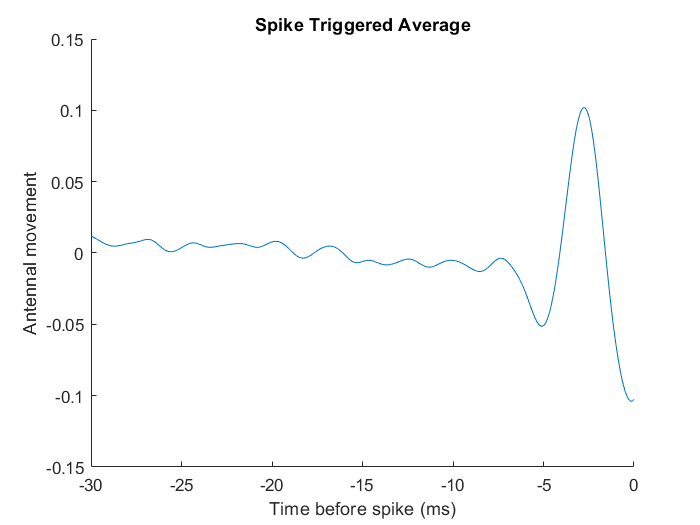


STA = mean(all_spike_triggers,1);
STA_normalised = STA/max(STA);
t= linspace(-stim_window*1000/fs, 0, length(STA));
figure;
plot(t, STA);
title('Spike Triggered Average');
xlabel('Time before spike (ms)');
ylabel('Antennal movement');
ax = gca;
ax.Box = "off";

## Get random stimuli

m = size(all_spike_triggers,1);
pattern_length = length(spike_triggers);
stimulus_prior = zeros([m pattern_length]);
r = randi([1 (length(stimulus)-pattern_length)],1,m);
for j=1:m
    stimulus_prior(j,:) = stimulus(randperm(size(stimulus,1),1),r(j):r(j)+pattern_length-1);
end


## Measure similarity between stimulus pattern and STA

all_patterns = [all_spike_triggers; stimulus_prior];
similarity_all = zeros([size(all_patterns,1) 1]);

for i = 1:size(all_patterns,1)
    s_STA = corrcoef(STA, all_patterns(i,:));
    similarity_all(i) = s_STA(2);
end

histogram(similarity_all);



## Calculate probabilities

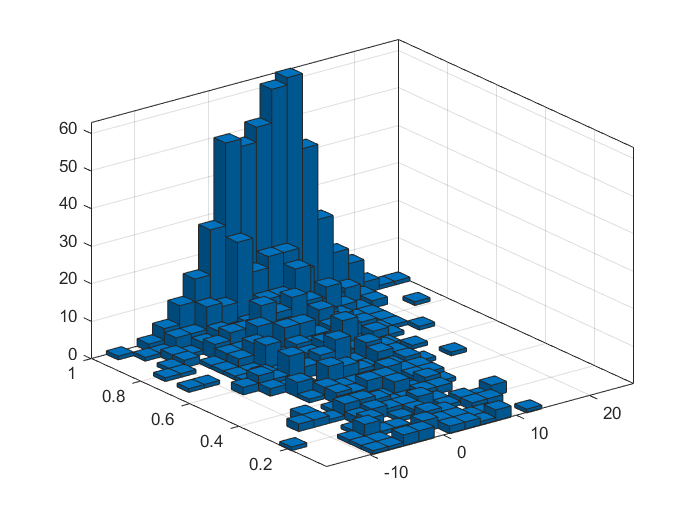

% stim_window = 0.015*fs; 
spike_window = fs*1e-3;


locs_ref = find(raster_data(1,:)==1);
ref = locs_ref(1);

stim_pattern = zeros(length(locs_ref),length(STA));
Pc_spike_stim = nan(1,length(locs_ref));
similarity_STA = nan(length(locs_ref),1);
similarity_STA_corrcoef = nan(length(locs_ref),1);

Nspikes = length(locs_ref);
for j = 1:length(locs_ref)
    
%     if locs_ref(j) > ref+spike_window
        ref = locs_ref(j);
        
        if ref>stim_window && (ref+spike_window)<length(stimulus)
            [spike_rows_trials, locs] = find(raster_data(:,ref-spike_window : ref+spike_window)==1);
            locs_trials = ref+locs-spike_window-1; % 11 to get the actual location from raster_data
            
            stim_pattern(j,:) = stimulus(ref-stim_window-1:ref-1);
            Nspikes(j) = length(locs);
            Pc_spike_stim(j) = length(locs)/Ntrials;
            s_STA = corrcoef(STA, stim_pattern(j,:), "Rows","complete");
            similarity_STA_corrcoef(j) = s_STA(2);
            similarity_STA(j) = dot(STA_normalised,(stim_pattern(j,:))');%/dot(STA,stimulus_prior(1,:));
            
%             s_ev = corrcoef(eVec1, stim_pattern(j,:));
%             similarity_ev(j) = s_ev(2);
            
        end
        
end

% T = table(stim_pattern, Pc_spike_stim, similarity_STA, similarity_ev);

histogram2(similarity_STA,Pc_spike_stim',20);

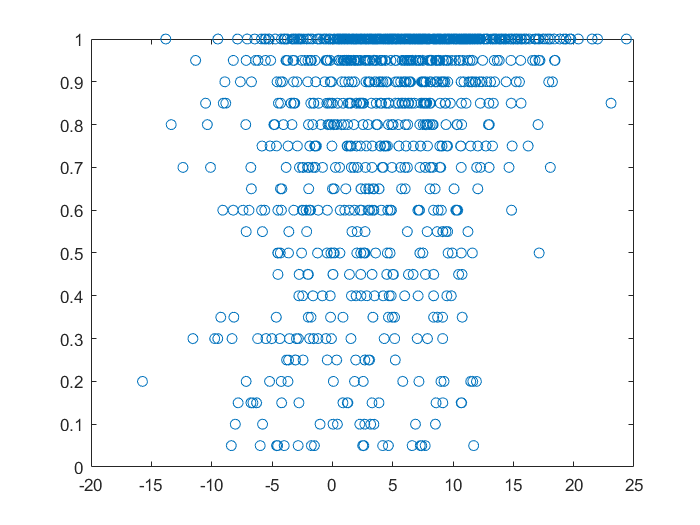

% histogram2(similarity_ev,Pc_spike_stim);

% [similarity_sorted,idx] = sort(similarity_STA);
% Pc_spike_stim_sorted = Pc_spike_stim(idx);

plot(similarity_STA,Pc_spike_stim, 'o');

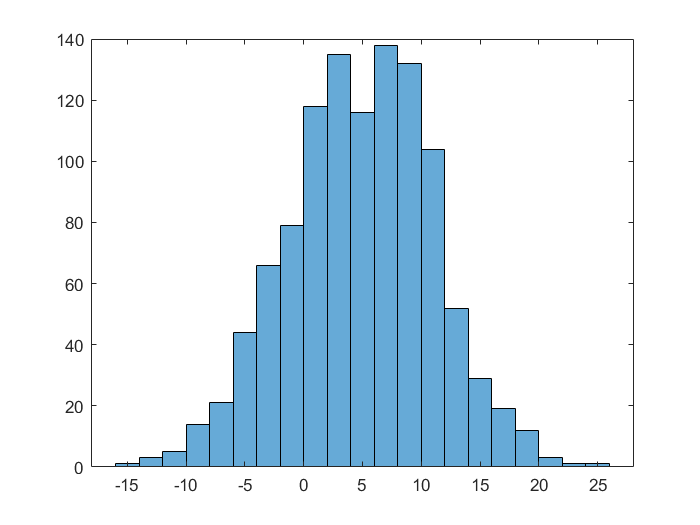


figure; histogram(similarity_STA);

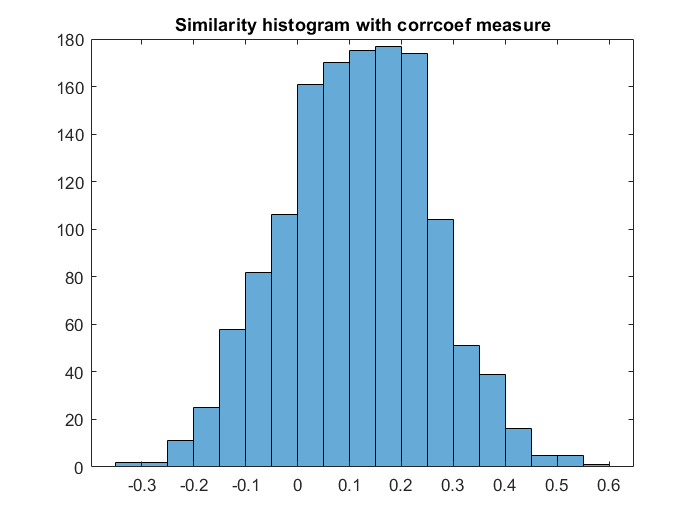

figure; histogram(similarity_STA_corrcoef);
title('Similarity histogram with corrcoef measure')

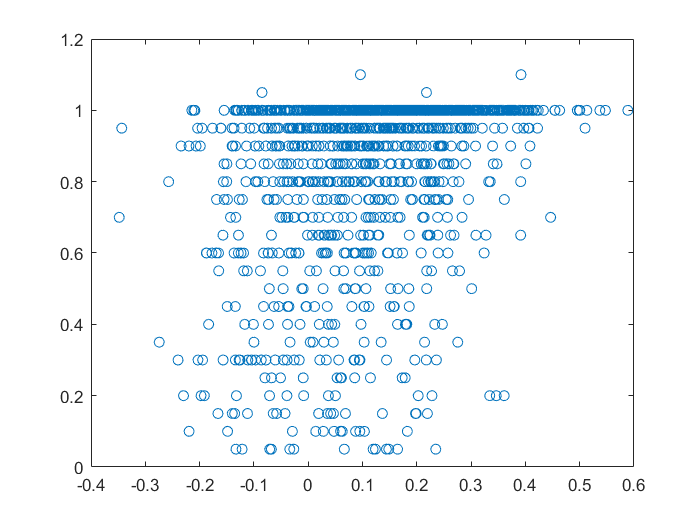

figure; plot(similarity_STA_corrcoef,Pc_spike_stim, 'o');

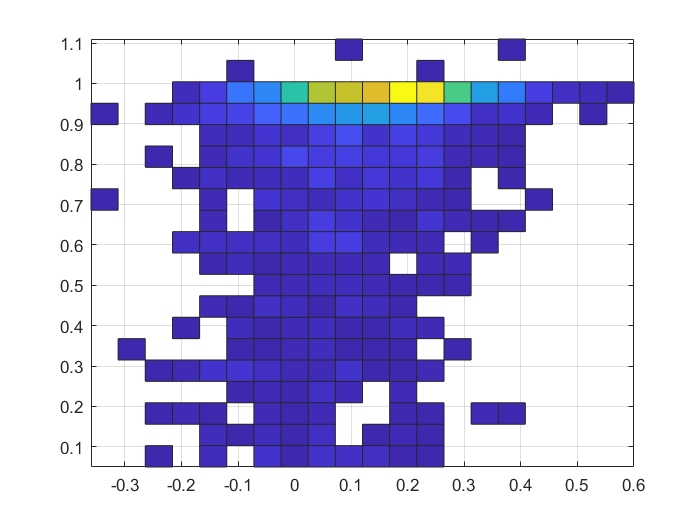

figure; histogram2(similarity_STA_corrcoef,Pc_spike_stim',20, 'DisplayStyle','tile');



% plot(similarity_ev, Pc_spike_stim, '.');
% f = fit(similarity_STA', Pc_spike_stim','poly2');
% plot(f,similarity_STA, Pc_spike_stim, '.');



step = 1;
stimLength = size(stimulus,2);
k=1;
Pc_sp_stim=[];
s_STA=[];

for i=1:step:(stimLength-stim_window-step-spike_window-1)
    stim_pattern = stimulus(1,i:i+stim_window);
    [~,locs] = find(raster_data(:,i+stim_window+1:i+stim_window+spike_window+1));
    
    Pc_sp_stim(k) = length(locs)/Ntrials;
    s = corrcoef(STA, stim_pattern);
    s_STA(k) = s(2); 
    k=k+1;
end

histogram2(s_STA,Pc_sp_stim, 'DisplayStyle','tile');



## Computing NLD function

% From Script_102_RetinaData_STA.m from Neural data analysis primer
S = stimulus_prior;
sta = STA/max(STA);
nbns = 15;
nbns_plot = nbns*3 ;

z = S*sta' ;                         % projecting the stimulus onto the STA (Equation 5)
                                % we assume that the response at time t depends on 
                                % the stimulus only through z(t) (a scalar quantity).
zx = max(abs(z(:)))+1e-3 ;          % finding the range of z values to generate appropriate bins
                                % (Equation 7)

bns = linspace(-zx,zx,nbns) ;       % bin edges
dbns = bns(2)-bns(1) ;              % size of each bin (equal for all bins here for simplicity)
ctr = bns(1:nbns-1)+dbns/2 ;        % bin centers

bns_plot = linspace(-zx,zx,nbns_plot) ;
dbns_plot = bns_plot(2)-bns_plot(1) ;
ctr_plot = bns_plot(1:nbns_plot-1)+dbns_plot/2 ;
                                % same for bins used for plotting 

% computing the nonlinear function g that converts stimulus 
% projections (z) to predicted firing rate (Equation 6). The 
% average response is computed at every bin of the projected 
% stimulus.

% Pf is the underlying stimulus distribution (projected on the 
% STA). normalized such that the integral over the distribution
% equals 1.

g = zeros(nbns,1) ;                 
[Pf,~,~,bS] = histcn(z,bns) ;
for ib = 1:nbns
g(ib) = mean(P.avg_gcfr(bS==ib)) ;
end
g(isnan(g)) = 0 ;
Pf  = Pf/(T*dbns) ;

% same at higher resolution bins (for plotting)
Pf_plot  = histcn(z,bns_plot) ;    
Pf_plot  = Pf_plot/(T*dbns_plot) ; 

% 3. Building an LN for general stimulus
% --------------------------------------

% first the STA model is defined to be a 
% smooth interpolation of the spiking nonlinearity
sta_model = @(x)interp1(bns,g,x,'pchip') ;                          

% then the model is passed through a linear rectifier, to 
% assure that the probability of a spike is non-negative
% the infinitesimal constant offset (1e-8) ensures that the 
% log-likelihood calculation does not diverge
sta_model_rect = @(x) heaviside(sta_model(x)).*sta_model(x)+1e-8 ; 

% finally the model has to be renormalized such that the number 
% of predicted spikes (on the training set) is fixed to what was 
% found in the experiment. This step is needed because of the 
% smoothing and rectifying operations.  
% The rectified smooth model is scaled such that for the training 
% set it predicts the total number of spikes found in the experiment.
nT_model = sum(sta_model_rect(z)) ; % the predicted total number of spikes before normalization
sta_model_rect_norm = @(x) sta_model_rect(x)*sum(R)/nT_model ; 